# Mobile robot short Project

### **Grup 11- Estudiants:**

- **Pol Casacuberta Gil**

- **Marta Granero i Martí**

**Link: **https://drive.matlab.com/sharing/b8a7f88a-dcb6-4c09-a328-ba6c7e737807

Given the kown workspace: Sensors_Data.mat, and  Enviroment.png

Answer the following question:

## Loading environment

clear
close all
clf

load("Encoder_Data.mat")

load("Sensors_Data.mat")

load("Laser_Data.mat")

## Pose estimation given encoder data (10%)

Before start:

- Open the Simulink model EKF_Pose_estimation.slx and get familiar with: 'Where2Find_Code.pdf'. 

- Have a look to section See an animation of the file: 3_MR_SP_support.mlx 

Every thing is done, the exercise consist in compile in a mlx file all the concepts.

1.- Implement in this mlx file:

a) Pose_theoric, asumme no noise. (review **Mobile Robot Kinematics** folder)

b) Pose_estimation by adding noise in odometry. review **Pose uncertanty** folder)

c) Ricatti equation for estimating the covariance matrix representing the uncertanty in the robot pose. 

2.- Display in a figure:

a) x,y poses for both trajectories: theoric and estimated 

b) ellipses representing x,y uncertanty. Do it every 15-20 poses.

c) represent uncertanty in orientation by adding a isosceles triange in front of the robot the base 

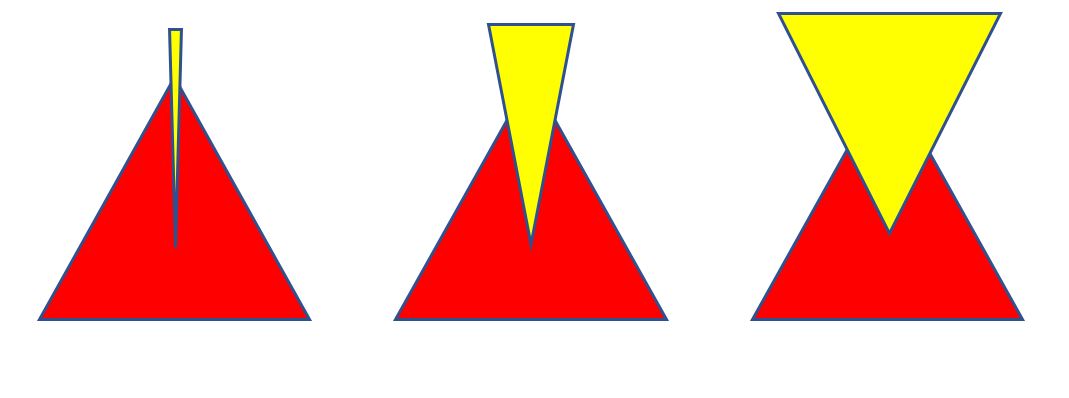

The robot will be represented by a triangle: Robot= [0 -0.2 0 1;0.4 0 0 1;0 0.2 0 1]

Record a movie of the robot moving along the corridor displaying both trajectories.

 See: help VideoWriter to get familiar with the matlab functions

ProcNoiseTheta = 9.0000e-06

Ts = 0.0200

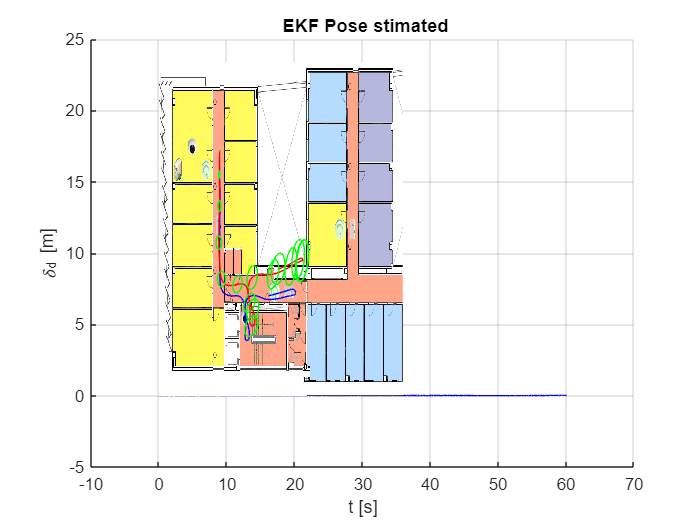

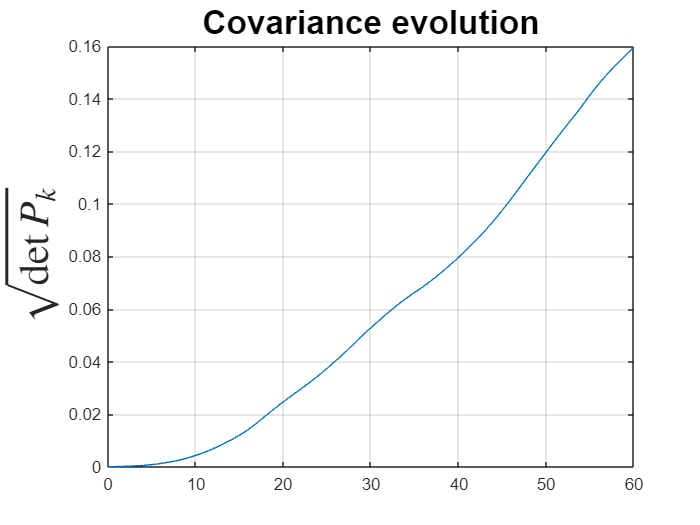

% Add your code here
sim("EKF_Pose_estimation_1.slx" )

### 1.a) Pose_theoric, assuming no noise

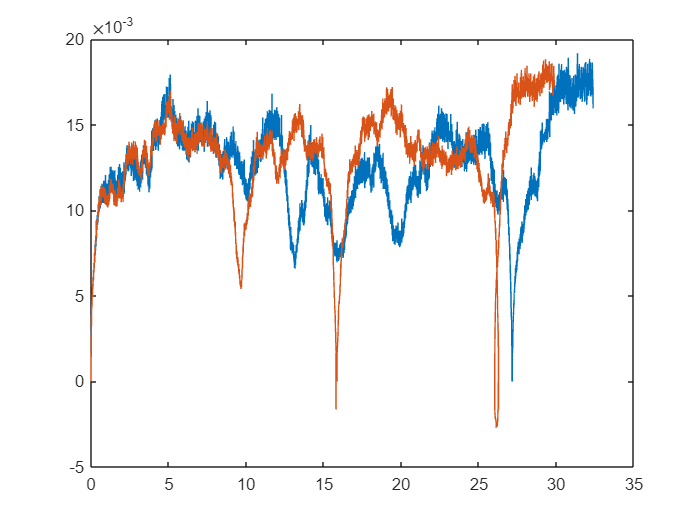

r = 0.1;
time = Ts;
t = R_acu(:,1);
L_inc = diff(L_acu(:,2));
R_inc = diff(R_acu(:,2));

delta_d=(R_inc+L_inc)/2;
delta_t=(R_inc-L_inc)/(W);

plot(R_acu(2:3004,2),R_inc(:))
hold on
plot(L_acu(2:3004,2), L_inc(:))

### Odometry displacement 

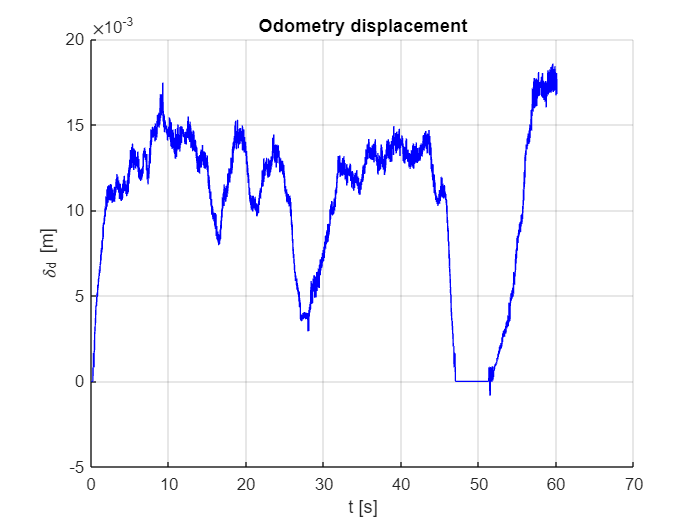

figure
hold on
grid on
title('Odometry displacement');
xlabel ('t [s]');
ylabel ('\delta_d [m]')
plot(t(2:end),delta_d,'b');

**Theoric trajectory calculation**

Initial_pose=transl(8.95,17.2,0)*trotz(-pi/2);
Initial_position=transl(Initial_pose);
Initial_orientation=-pi/2;
x(1)=Initial_position(1);
y(1)=Initial_position(2);
o(1)=Initial_orientation;
for i=1:(length(t)-1)
    x(i+1) = x(i)+delta_d(i)*cos(o(i));
    y(i+1) = y(i)+delta_d(i)*sin(o(i));
    o(i+1) = mod(o(i)+delta_t(i),2*pi);
end

### 1.b) Pose_estimation by adding noise in odometry

noise_std = 0.002; % adjust as needed
ProcNoiseTheta;

ProcNoiseTheta = 9.0000e-06

ProcNoiseD;

ProcNoiseD = 3.6100e-04

delta_d_n = delta_d + randn(length(t)-1,1)*noise_std;
delta_t_n = delta_t + randn(length(t)-1,1)*noise_std;

**Odometry displacement with noise**

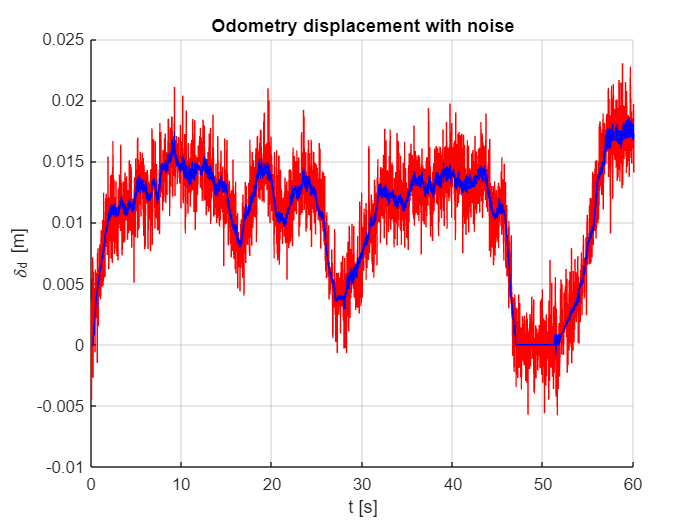

figure
hold on

plot(t(2:end),delta_d_n,'r')
xlim ([0 Tf])
grid on
title('Odometry displacement with noise')
xlabel ('t [s]')
ylabel ('\delta_d [m]')
plot(t(2:end),delta_d,'b')

**Estimated (noisy) trajectory calculation**

x_n(1)=Initial_position(1);
y_n(1)=Initial_position(2);
o_n(1)=Initial_orientation;
for i=1:(length(t)-1)
    x_n(i+1) = x_n(i)+delta_d_n(i)*cos(o_n(i));
    y_n(i+1) = y_n(i)+delta_d_n(i)*sin(o_n(i));
    o_n(i+1) = mod(o_n(i)+delta_t_n(i),2*pi);
end

### 1.c) Ricatti equation

V = [ProcNoiseD 0; 0 ProcNoiseTheta];
F_x(:,:,i)= [1 0 -delta_d(1)*sin(o(1));....
    0 1  delta_d(1)*cos(o(1));....
    0 0 1];
F_v(:,:,i) = [cos(o(1)) 0;sin(o(1)) 0;0 1];
P(:,:,i) = F_x(:,:,1)*(eye(3)*0.0001)*F_x(:,:,1)' + F_v(:,:,1)*...
    [V(1) 0; 0 V(2,2)]*F_v(:,:,1)';
for i=2:(length(t))-1
    F_x(:,:,i) = [1 0 -delta_d(i) * sin(o(i)); 0 1 delta_d(i) * cos(o(i)); 0 0 1];
    F_v(:,:,i) = [cos(o(i)) 0; sin(o(i)) 0; 0 1];
    P(:,:,i) = F_x(:,:,i)*P(:,:,i-1)*F_x(:,:,i)' + F_v(:,:,i)*[V(1) 0; 0 V(2,2)]*F_v(:,:,i)';
end

**Covariance evolution**

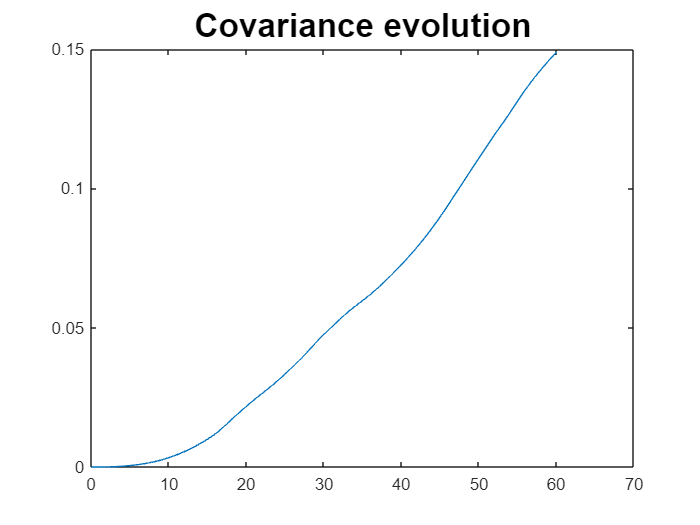

for i=2:length(P)
    a(i)=sqrt(det(P(:,:,i)));
end

figure
grid on
plot((0:0.02:3002*0.02),a)

title ('Covariance evolution',"FontSize",20)

### 2.a) x,y poses for both trajectories: theoric and estimated

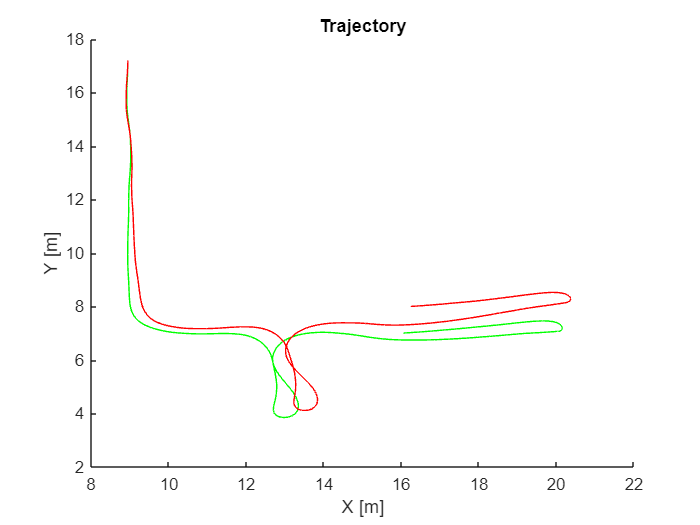

figure
hold on
title('Trajectory')
xlabel ('X [m]')
ylabel ('Y [m]')
plot(x,y,'g')
plot(x_n,y_n,'r')

### 2.b) ellipses representing x,y uncertanty. Do it every 15-20 poses.

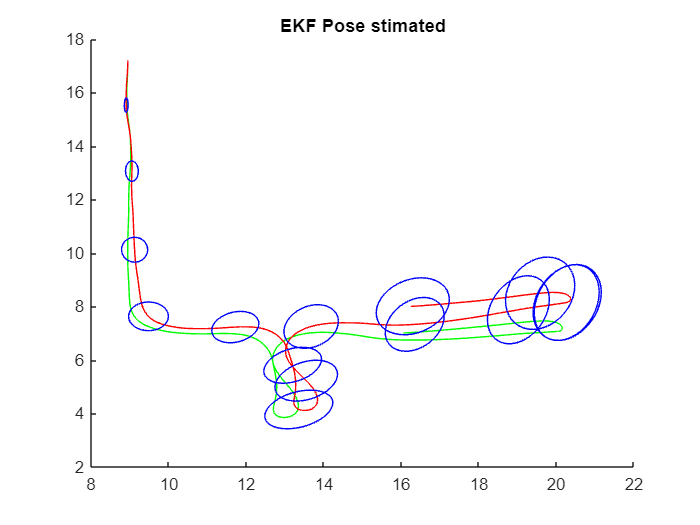

figure
hold on
plot(x,y,'g')
plot(x_n,y_n,'r')

hold on
for i=1:round(length(t)/15):length(t)
    plot_ellipse(P(1:2,1:2,i),[x_n(i), y_n(i)],'b');
    title('EKF Pose stimated');
end

### 2.c) represent uncertanty in orientation by adding a isosceles triange in front of the robot the base 

The robot will be represented by a triangle: Robot= [0 -0.2 0 1;0.4 0 0 1;0 0.2 0 1]

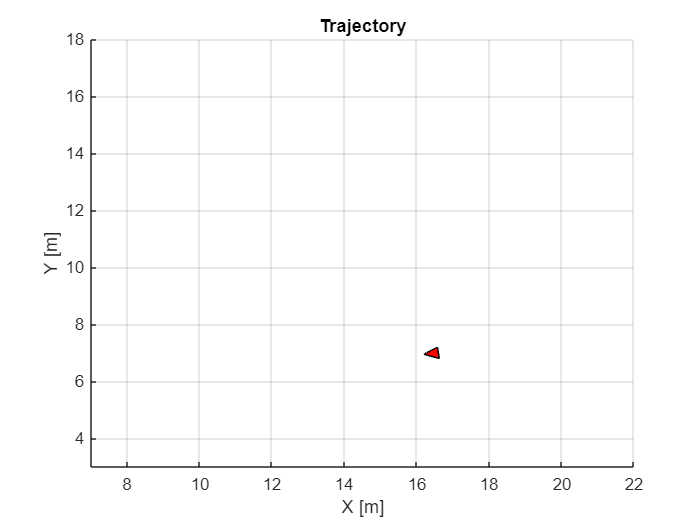

Error using waitbar
The second argument must be a message character vector or a handle to an existing waitbar.

Robot = [0 -0.2 0 1;0.4 0 0 1;0 0.2 0 1];

totalFrames = length(x);

F = zeros(totalFrames);

% Create waitbar
h = waitbar(0, 'Processing Frames...');

for i=1:totalFrames
    clf
    figure(1)
    grid on
    hold on
    title('Trajectory')
    xlabel ('X [m]')
    ylabel ('Y [m]')
    xlim([7,22])
    ylim([3,18])
    plot(x,y,'g')
    plot(x_n,y_n,'r')

    robotPosition = (transl(x(i),y(i),0)*trotz(o(i))*Robot')';
    robotTriangle = polyshape(robotPosition(:,1),robotPosition(:,2));
    plot(robotTriangle,'FaceColor','r','FaceAlpha',1);
    u = (sin(P(3,3,i)/2)+0.0001)*20;
    Cone = [0.1 0 0 1; 0.5 u 0 1; 0.5 -u 0 1];
    conePosition = (transl(x(i),y(i),0)*trotz(o(i))*Cone')';
    coneTriangle = polyshape(conePosition(:,1),conePosition(:,2));
    plot(coneTriangle,'FaceColor','y','FaceAlpha',1);
    drawnow;
    F(i) = getframe(gcf);

    % Update the waitbar
    waitbar(i / totalFrames, h, sprintf('Processing Frame %d of %d', i, totalFrames));

end

% Close waitbar
close(h);

vidwriter = VideoWriter('RobotUncertainityAngle.mp4','MPEG-4');
vidwriter.FrameRate = 50;
open(vidwriter);
for i=1:length(F)
    writeVideo(vidwriter, F(i));
end
close(vidwriter)


% Robot = [0 -0.2 0 1;0.4 0 0 1;0 0.2 0 1];
% robotTriangle = polyshape(Robot(:,1),Robot(:,2));
% 
% totalFrames = size(polar_laser_data, 1) * 20 - 1;
% h = waitbar(0, 'Processing Frames');
% 
% for i=1:totalFrames
%     clf
%     figure(1)
%     grid on
%     hold on
%     title('Trajectory')
%     xlabel ('X [m]')
%     ylabel ('Y [m]')
%     xlim([7,22])
%     ylim([3,18])
%     % plot(x_c,y_c,'-b')
% 
%     % robotPose = transl(log2.CorrectedPositionX(i),log2.CorrectedPositionY(i),0)*...
%     % trotz(log2.CorrectedPositionO(i));
% 
%     robotPosition = (robotPose*Robot')';
%     robotTriangle = polyshape(robotPosition(:,1),robotPosition(:,2));
%     plot(robotTriangle,'FaceColor','r','FaceAlpha',1);
% 
%     if mod(i,10) == 0
%         res = [];
%         ang = linspace(-120*pi/180,120*pi/180,682);
%         [pointsX, pointsY] = pol2cart(ang, ...
%             polar_laser_data(floor(i/(0.4/time))+1,2:683)/1000);
%         pointsL = [pointsX; pointsY];
%         idx = 1;
%         for j=1:682
%             if(pointsL(1,j) ~= 0 || pointsL(2,j) ~= 0)
%                 res(:,idx) = pointsL(:,j);
%                 idx = idx + 1;
%             end
%         end
%         if(~isempty(res))
%             scatter(res(1,:),res(2,:),2,'filled','MarkerFaceColor',[1 0 0]);
%         end
%         drawnow;
%     end
% 
%     F2(i) = getframe(gcf);
% 
%     % Update the waitbar
%     waitbar(i / totalFrames, h, sprintf('Processing Frame %d of %d', i, totalFrames));
% end

% Close the waitbar
close(h);

vidwriter = VideoWriter('RobotReferenceFrame.mp4','MPEG-4');
vidwriter.FrameRate = 50;
open(vidwriter);
for i=1:length(F2)
    writeVideo(vidwriter, F2(i));
end
close(vidwriter)

## Driving the Robot (20%)

Based on what you learn in motion arquitectures use the Goint2point for driving the robot. Use 'frontend.m' function to introduce way points such to recreate a trajectory similar to the past section.

Make a video displaying both trajectories: estimated and theoric. Add the ellipses to visualize uncertanty.

Notice that in this exercise the trajectoryies appear as the robot moves.

% % Add your code here
% load("way_points_2.mat")
% 
% % Calculate all the intermidiate points to the 
% n_points= size(wp, 2);
% startPose = wp(:,1)';
% startPose(3) = 0 ;
% poses = [];
% figure
% %Drawing all the waypoints
% scatter(wp(1,:), wp(2,:),'Marker','o','MarkerEdgeColor','b');
% title('Following a trayectory with waypoints');
% hold on;
% axis equal
% grid
% xlabel("X");
% ylabel("Y");
% 
% Robot.V = [0 -0.2 0;
%            0.4 0 0;
%            0 0.2 0;];
% Robot.F = [1,2,3];
% Robot.V = Robot.V * 20;
% fig_robot = [];
% Kv = 0.9; % Velocity Gain
% Kh = 4; % Head Gain
% minStopDistance = 2;
% for i = 2:n_points;
%     goal = wp(:,i)';
%     poses_current = goToPoint(goal,startPose,Kv,Kh,minStopDistance);
%     for j = 1:size(poses_current,1)-1
%         pose_matrix = transl(poses_current(j,1),poses_current(j,2),0)*trotz(poses_current(j,3));
%         CG = (max(Robot.V) + min(Robot.V))/2;
%         T = pose_matrix*transl(-CG);
%         aux = [Robot.V ones(length(Robot.V'),1)]' ; 
%         robot = (T * aux)';
%         robot(:,4) = [];
%         delete(fig_robot);
%         fig_robot=patch("Faces",Robot.F,"Vertices",robot, 'FaceAlpha', 0, ...
%                  'EdgeColor',   [1,0,0]);
%         plot(poses_current(j:j+1,1),poses_current(j:j+1,2),"Color",'c');
% 
% %       pause(0.05);
%     end
%     pause(0.05);
%     startPose = poses_current(end,:);
%     poses  = [poses; poses_current];
% 
% end
% legend('waypoints','path');

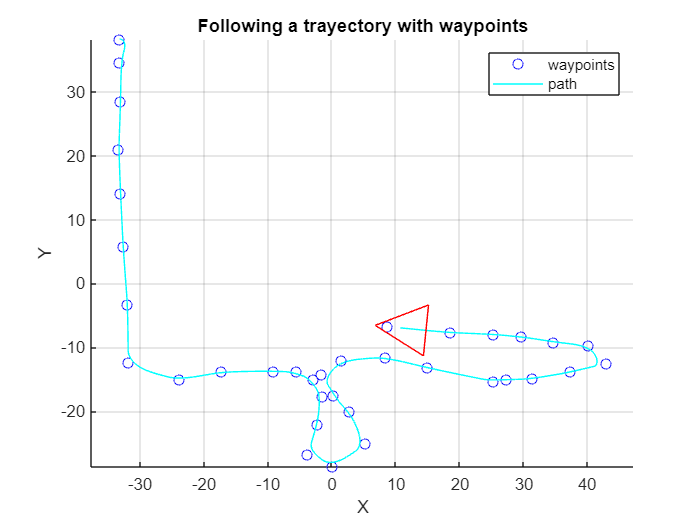

load("way_points_2.mat")


% Calculate all the intermediate points
n_points = size(wp, 2);
startPose = wp(:,1)';
startPose(3) = 0;
poses = [];

Robot.V = [0 -0.2 0;
           0.4 0 0;
           0 0.2 0;];
Robot.F = [1,2,3];
Robot.V = Robot.V * 20;
fig_robot = [];
Kv = 0.9; % Velocity Gain
Kh = 4; % Head Gain
minStopDistance = 2;


% % Define parameters for noise
% meanNoise = 1;                % Mean of the noise
% stdDevNoise = 0.5;            % Standard deviation of the noise
% 
% % Precalculate all poses with noise
% for i = 2:n_points
%     goal = wp(:,i)';
%     poses_current = goToPoint(goal, startPose, Kv, Kh, minStopDistance);
% 
%     % Add noise to each pose
%     noise = stdDevNoise * randn(size(poses_current));
%     poses_current = poses_current + noise;
% 
%     poses = [poses; poses_current];
%     startPose = poses_current(end,:);
% end

bar = waitbar(0, 'Calculating poses...');
% Precalculate all poses
for i = 2:n_points
    goal = wp(:,i)';
    poses_current = goToPoint(goal, startPose, Kv, Kh, minStopDistance);
    poses = [poses; poses_current];
    startPose = poses_current(end,:);
    % Update waitbar
    waitbar(i/n_points, bar, sprintf('Processing point %d of %d', i, n_points));
end
close(bar); % Close the waitbar when the loop is finished
% Plotting the trajectory and waypoints
figure
scatter(wp(1,:), wp(2,:), 'Marker', 'o', 'MarkerEdgeColor', 'b');
hold on;
axis equal
grid
xlabel("X");
ylabel("Y");
title('Following a trajectory with waypoints');

% Plotting the precalculated poses
fig_robot = [];
n_poses = size(poses,1)-1;
for j = 1:n_poses
    pose_matrix = transl(poses(j,1), poses(j,2), 0) * trotz(poses(j,3));
    CG = (max(Robot.V) + min(Robot.V))/2;
    T = pose_matrix * transl(-CG);
    aux = [Robot.V ones(length(Robot.V'),1)]';
    robot = (T * aux)';
    robot(:,4) = [];
    delete(fig_robot);
    fig_robot = patch("Faces", Robot.F, "Vertices", robot, 'FaceAlpha', 0, 'EdgeColor', [1,0,0]);
    plot(poses(j:j+1,1), poses(j:j+1,2), "Color", 'c');
    if mod(j, 10) == 0
        pause(0.01); % Pause after every 10 poses
    end
   
end

legend('waypoints', 'path');

## Localization (30%)

While driving the Robot in the last section Localize the Robot  by using the Similarity Transform. 

Visit again the folder 11_Localization for inspiration.

### Land Marks

Use the given Land Marks. They are known. They can be extracter from laser data, there are easy algorithms for finding they, like corner detection, etc ...

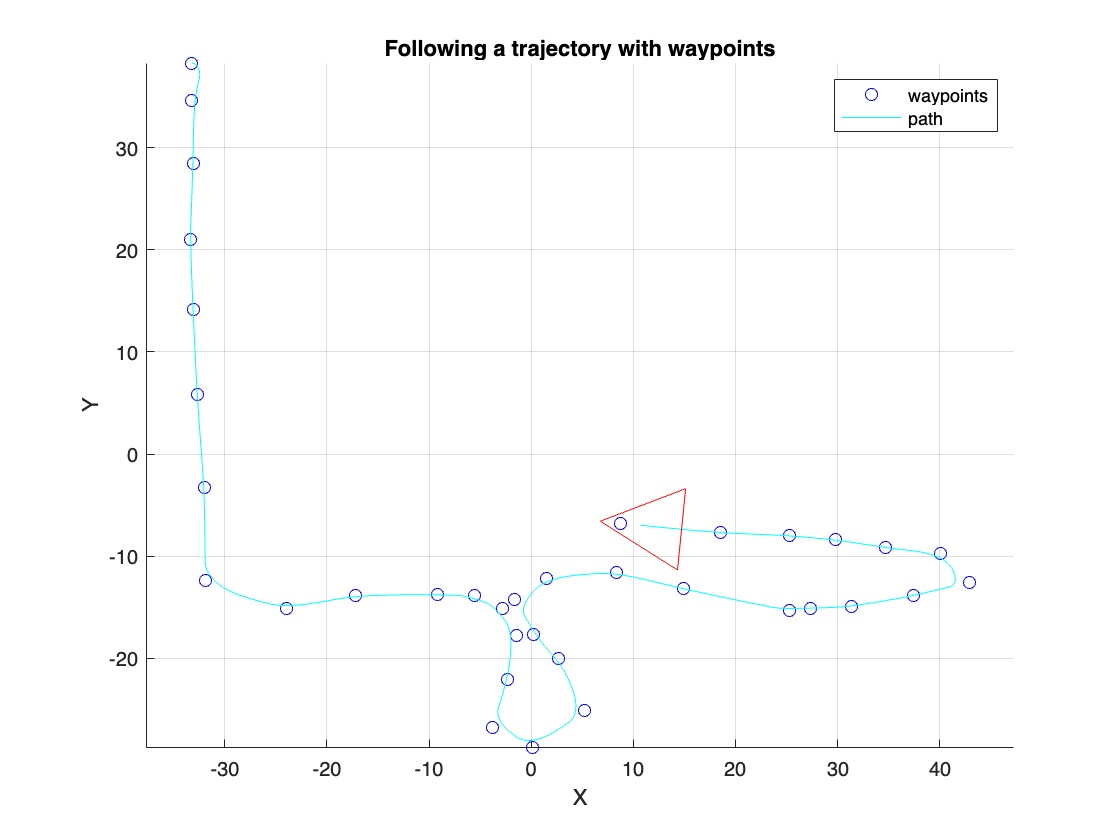

Lmk= [7.934 16.431 0 1;...

    9.583 16.431 0 1;...
    9.584 13.444 0 1;...
    9.584 10.461 0 1;...
    7.973 10.534 0 1;...
    7.934  7.547 0 1;...
    9.584  6.654 0 1;...
    13.001  6.525 0 1;...
    17.007  8.136 0 1];

### Plot Land Marks 

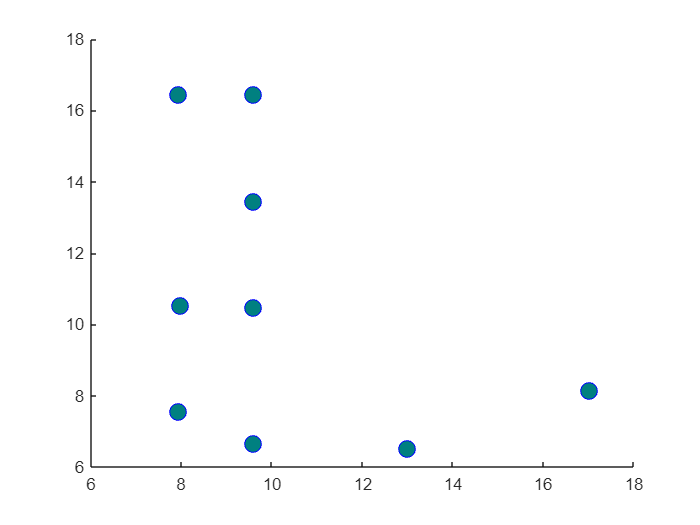

clf
hold on
sz = 100;
s=scatter(Lmk(:,1),Lmk(:,2),sz);
s.LineWidth = 0.6;
s.MarkerEdgeColor = 'b';
s.MarkerFaceColor = [0 0.5 0.5];

TimeStamp = t;
EstimatedNoisyX = x_n';
EstimatedNoisyY = y_n';
EstimatedNoisyO = o_n';
NumberLandmarksReal = sum(((l_s_d~=0) | (l_s_d~=0)),2);
NumberLandmarksLog = [NumberLandmarksReal; 0; 0; 0];
log = table(TimeStamp,EstimatedNoisyX,EstimatedNoisyY,EstimatedNoisyO,...
    NumberLandmarksLog)

log = 3004×5 table
    TimeStamp    EstimatedNoisyX    EstimatedNoisyY    EstimatedNoisyO    NumberLandmarksLog
    _________    _______________    _______________    _______________    __________________

         0             8.95               17.2             -1.5708                0         
      0.02             8.95             17.199              4.7155                0         
      0.04             8.95             17.195              4.7143                0         
      0.06             8.95               17.2              4.7129                0         
      0.08             8.95             17.198                4.71                0         
       0.1             8.95             17.197              4.7098                0         
      0.12             8.95               17.2              4.7096

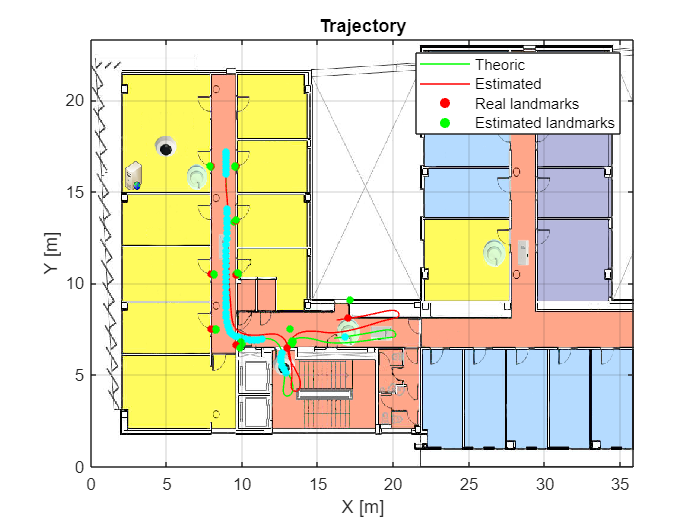

clf
figure

I=imread('Enviroment.png');
x_ima=[0 35.9];
y_ima=[23.31 0];
image(I,'XData',x_ima,'YData',y_ima);
axis xy;
plotTrajectories(x,y,x_n,y_n);

LandMark= lmk';
for i=1:length(l_s_b)
    Robot_pose_est = transl(x_n(i),y_n(i),0)*trotz(o_n(i));
    if log.NumberLandmarksLog(i) > 1
        ld = l_s_d(i,:);
        lb = l_s_b(i,:);
        [lmx, lmy] = pol2cart(lb,ld);
        lmw = [];
        A = [];
        B = [];
        idx = 1;
        for j=1:9
            if lmx(j) ~= 0 || lmy(j) ~= 0
                lmw(idx,:) = Robot_pose_est*[lmx(j); lmy(j); 0; 1];
                scatter(LandMark(1,j),LandMark(2,j),20, 'r','filled');
                scatter(lmw(idx,1),lmw(idx,2),20, 'g','filled');

                A = [A;[LandMark(1,j),LandMark(2,j),1,0]];
                A = [A;[LandMark(2,j),-LandMark(1,j),0,1]];
                B = [B; lmw(idx,1); lmw(idx,2)];
                idx = idx + 1;
            end
        end
        X = (A'*A)\(A'*B);
        tx_ST = X(3);
        ty_ST = X(4);
        alpha_ST = atan2(X(2),X(1));
        Robot_m=transl(Robot_pose_est);
        Robot_error= transl(-tx_ST,-ty_ST,0)*trotz(alpha_ST)*[Robot_m;1];
        scatter(Robot_error(1),Robot_error(2),20, 'cyan','filled');
    end

end
legend('Theoric','Estimated','Real landmarks','Estimated landmarks')

### Correct the noisy trajectory. 

Pay attention to the relationship of the variables

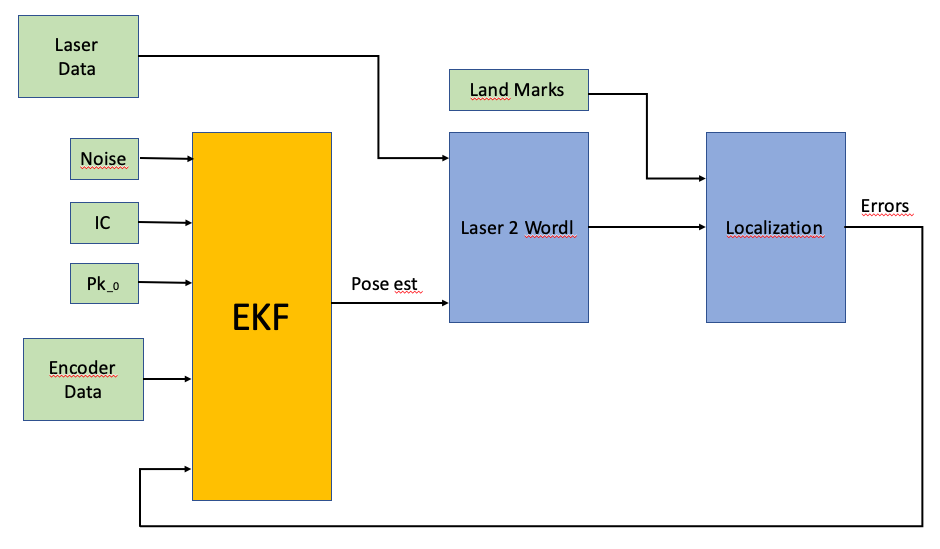

Update the estimated covarianze matrix by the sensor, knowing that the Laser scanner has and acuraccy 4 mm with a standard deviation of 0.2 mm.

1.- Display in a figure: the map, theoric trajectory (no noise) and the corrected trajectory.

2.- Make a 'log' with the following columns:  estimated noisy pose, corrected position, number of Land-marks seen,  and the errors and the covariance matrix Pk.

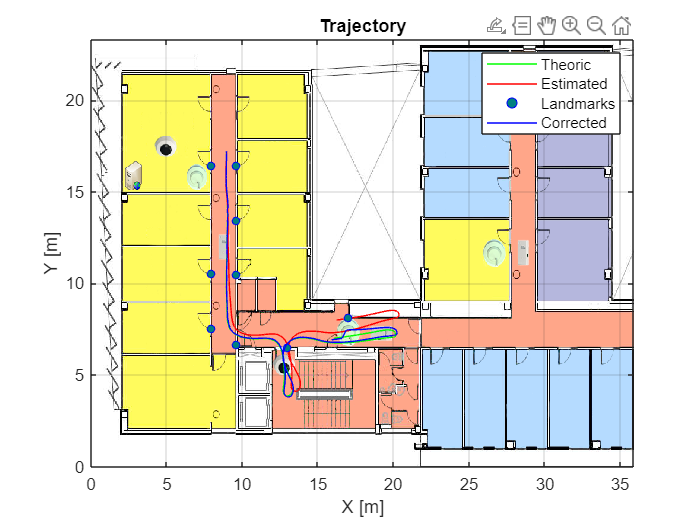

clf
figure
I=imread('Enviroment.png');
x_ima=[0 35.9];
y_ima=[23.31 0];
image(I,'XData',x_ima,'YData',y_ima);
axis xy
plotTrajectories(x,y,x_n,y_n);
lmk= [7.934 16.431 0 1;...
    9.583 16.431 0 1;...
    9.584 13.444 0 1;...
    9.584 10.461 0 1;...
    7.973 10.534 0 1;...
    7.934 7.547 0 1;...
    9.584 6.654 0 1;...
    13.001 6.525 0 1;...
    17.007 8.136 0 1];
hold on
s=scatter(lmk(:,1),lmk(:,2),20);
s.LineWidth = 0.6;
s.MarkerEdgeColor = 'b';
s.MarkerFaceColor = [0 0.5 0.5];
LandMark= lmk';

x_c = [];
y_c = [];
o_c = [];
x_c(1) = x_n(1);
y_c(1) = y_n(1);
o_c(1) = o_n(1);
Position = [];
for i=1:length(l_s_b)
    Robot_pose_est = transl(x_c(i),y_c(i),0)*trotz(o_c(i));
    if log.NumberLandmarksLog(i) > 1
        ld = l_s_d(i,:);
        lb = l_s_b(i,:);
        [lmx, lmy] = pol2cart(lb,ld);
        lmw = [];
        A = [];
        B = [];
        idx = 1;
        for j=1:9
            if lmx(j) ~= 0 || lmy(j) ~= 0
                lmw(idx,:) = Robot_pose_est*[lmx(j); lmy(j); 0; 1];

                A = [A;[LandMark(1,j),LandMark(2,j),1,0]];
                A = [A;[LandMark(2,j),-LandMark(1,j),0,1]];
                B = [B; lmw(idx,1); lmw(idx,2)];
                idx = idx + 1;
            end
        end
        X = (A'*A)\(A'*B);
        tx_ST = X(3);
        ty_ST = X(4);
        alpha_ST = atan2(X(2),X(1));
        newPoint = transl(-tx_ST,-ty_ST,0)*trotz(alpha_ST)*[x_c(i) y_c(i) 0 1]';
        x_c(i) = newPoint(1);
        y_c(i) = newPoint(2);
        o_c(i) = alpha_ST+o_c(i);
    end
    Position(:,i) = [x_c(i),y_c(i),0]';

    x_c(i+1) = x_c(i)+delta_d_n(i)*cos(o_c(i));
    y_c(i+1) = y_c(i)+delta_d_n(i)*sin(o_c(i));
    o_c(i+1) = mod(o_c(i)+delta_t_n(i),2*pi);
end

plot(Position(1,1:end),Position(2,1:end),'b');
legend('Theoric','Estimated','Landmarks','Corrected')

TimeStamp = t(1:end-3);
EstimatedNoisyX = x_n(1:end-3)';
EstimatedNoisyY = y_n(1:end-3)';
EstimatedNoisyO = o_n(1:end-3)';

CorrectedPositionX = x_c';
CorrectedPositionY = y_c';
CorrectedPositionO = o_c';
log2 = table(TimeStamp,EstimatedNoisyX,EstimatedNoisyY,EstimatedNoisyO,...
    CorrectedPositionX,CorrectedPositionY,CorrectedPositionO,NumberLandmarksReal)

log2 = 3001×8 table
    TimeStamp    EstimatedNoisyX    EstimatedNoisyY    EstimatedNoisyO    CorrectedPositionX    CorrectedPositionY    CorrectedPositionO    NumberLandmarksReal
    _________    _______________    _______________    _______________    __________________    __________________    __________________    ___________________

         0             8.95               17.2             -1.5708                8.95                  17.2               -1.5708                   0         
      0.02             8.95             17.199              4.7155                8.95                17.199                4.7155                   0         
      0.04             8.95             17.195              4.7143 

## Mapping (10%)

Make a movie of laser data in Robot reference frame. See the video  of ATENEA: [Movie of the Laser Data seen in Robot Reference FrameURL](https://atenea.upc.edu/mod/url/view.php?id=3257292)

Make a video of laser data in Wordl Reference frame. Use here the code of the last TODO Lab about laser data. 

Display laser data every 2.5 m and erasing the previous walls after 200ms for better understanding.

See the video: '3_mapping.mp4' for inspiration

Robot Reference Frame:

Robot = [0 -0.2 0 1;0.4 0 0 1;0 0.2 0 1];
robotTriangle = polyshape(Robot(:,1),Robot(:,2));

totalFrames = size(polar_laser_data, 1) * 20 - 1;


walls =

     []



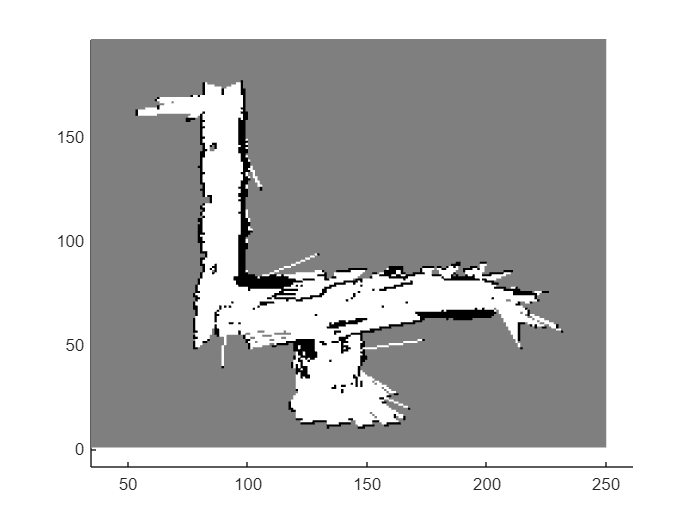

h = waitbar(0, 'Processing Frames');

for i=1:totalFrames
    clf
    figure(1)
    grid on
    hold on
    xlim([-0.4 1])
    ylim([-1.5 1.5])

    plot(robotTriangle,'FaceColor','r','FaceAlpha',1);

    ang = linspace(-120*pi/180,120*pi/180,682);
    [pointsX, pointsY] = pol2cart(ang, ...
        polar_laser_data(floor(i/(0.4/time))+1,2:683)/1000);
    pointsL = [pointsX; pointsY];
    idx = 1;
    for j=1:682
        if(pointsL(1,j) ~= 0 || pointsL(2,j) ~= 0)
            res(:,idx) = pointsL(:,j);
            idx = idx + 1;
        end
    end
    scatter(res(1,:),res(2,:),2,'filled','MarkerFaceColor',[1 0 0]);

    F2(i) = getframe(gcf);

    % Update the waitbar
    waitbar(i / totalFrames, h, sprintf('Processing Frame %d of %d', i, totalFrames));
end
% Close the waitbar
close(h);

vidwriter = VideoWriter('RobotReferenceFrame.mp4','MPEG-4');
vidwriter.FrameRate = 50;
open(vidwriter);
for i=1:length(F2)
    writeVideo(vidwriter, F2(i));
end
close(vidwriter)

Robot World reference frame:

Robot = [0 -0.2 0 1;0.4 0 0 1;0 0.2 0 1];
walls = [];
for i=1:size(polar_laser_data,1)*20-1
    if mod(i,10) == 0
        walls = [];
    end

    robotPose = transl(log2.CorrectedPositionX(i),log2.CorrectedPositionY(i),0)*...
        trotz(log2.CorrectedPositionO(i));
    if log2.NumberLandmarksReal(i) > 0
        ang = linspace(-120*pi/180,120*pi/180,682);

        [pointsX, pointsY] = pol2cart(ang, ...
            polar_laser_data(floor(i/(0.4/time))+1,2:683)/1000);
        pointsL = [pointsX; pointsY; zeros(1,682); ones(1,682)];
        idx = 1;
        for j=1:682
            if(pointsL(1,j) ~= 0 || pointsL(2,j) ~= 0)
                walls(:,idx) = robotPose*pointsL(:,j);
                idx = idx + 1;
            end
        end
    end
    clf
    figure(1)
    grid on
    hold on
    title('Trajectory')
    xlabel ('X [m]')
    ylabel ('Y [m]')
    xlim([7,22])
    ylim([3,18])
    plot(x_c,y_c,'-b')


    robotPosition = (robotPose*Robot')';
    robotTriangle = polyshape(robotPosition(:,1),robotPosition(:,2));
    plot(robotTriangle,'FaceColor','r','FaceAlpha',1);

    if(~isempty(walls))
        scatter(walls(1,:),walls(2,:),2,'filled','MarkerFaceColor',[1 0 0]);
    end
    drawnow;
    F(i) = getframe(gcf);
end


% vidwriter = VideoWriter('RobotMapping.mp4','MPEG-4');
% vidwriter.FrameRate = 50;
% open(vidwriter);
% for i=1:length(F)
% writeVideo(vidwriter, F(i));
% end
% close(vidwriter)

## Occupancy grid (30%)

Use Breshehan algorithm to build the map. Do it only when Land Marks are avalaible and the trajectory have been corrected.

Use the idea behind the line tracing: Visit: https://es.wikipedia.org/wiki/Algoritmo_de_Bresenham

See: Mapping.mlx and '4_occupancy.mp4' for inspiration

vidwriter = VideoWriter('Occupancy.avi','Motion JPEG AVI');
vidwriter.FrameRate = 3;
open(vidwriter);
walls = []
A=ones(250,250);
clear F

bar = waitbar(0, 'Processing Frames');
totalIterations = (size(polar_laser_data, 1) - 1) * 20;

for i=20:20:size(polar_laser_data,1)*20-1
    walls = [];
    robotPose = transl(log2.CorrectedPositionX(i),log2.CorrectedPositionY(i),0)*...
        trotz(log2.CorrectedPositionO(i));
    if log2.NumberLandmarksReal(i) > 0
        ang = linspace(-120*pi/180,120*pi/180,682);
        [pointsX, pointsY] = pol2cart(ang,...
            polar_laser_data(floor(i/(0.4/time))+1,2:683)/1000);
        pointsL = [pointsX; pointsY; zeros(1,682); ones(1,682)];
        idx = 1;
        for j=1:682
            if(pointsL(1,j) ~= 0 || pointsL(2,j) ~= 0)
                walls(:,idx) = robotPose*pointsL(:,j);
                idx = idx + 1;
            end
        end
    end
    clf
    
    figure(1)
    hold on

    for j=1:length(walls)

        rob_position = transl(robotPose)*10;
        destination = round(walls(1:2,j)*10);

        rrob_position = round( rob_position(1:2));
        [l_x, l_y] = bresenham(rrob_position(1), rrob_position(2) , destination(1), destination(2));
        L=size(l_x,1);

        for k=1:L
            A(l_y(k),l_x(k)) = 2;
        end
        A(destination(2),destination(1)) = 0;

    end
    A(round(rob_position(2)),round(rob_position(1))) = 0;
    h = pcolor(A);
    set(h, 'EdgeColor', 'none');
    colormap(gray(3))
    grid off
    drawnow
    writeVideo(vidwriter,getframe(gcf))
    A(round(rob_position(2)),round(rob_position(1))) = 2;

   % Update progress bar
    waitbar(i / totalIterations, bar, sprintf('Processing Frame %d of %d', i, totalIterations));
    
end
% Close waitbar
close(bar);
close(vidwriter)

function plotTrajectories(x,y,xn,yn)

grid on
hold on
title('Trajectory')
xlabel ('X [m]')
ylabel ('Y [m]')
plot(x,y,'g')
plot(xn,yn,'r')

end


function [poses] = goToPoint(goal,startPose,Kv,Kh,minStopDistance)
%   Input:
%     goal - goal point
%     startPose - vehicles' start pose
%     Kv - Velocity Gain
%     Kh - % Head Gain
%     minStopDistance - minStopDistance to the goal point to consider that
%     we have arrived to the goal.
%   Output: all the poses from startPose until it arrive to a less than
%   minStopDistance to goal

    I_kine = @(v_x, psi,r,S) ...
    [(1/r)*v_x+ (1/r)*S*psi (1/r)*v_x-(1/r)*S*psi];

    odo = @(phi_r, phi_l,r,S,ts) ...
    [(1/2)*r*(phi_r+phi_l)*ts (r/(2*S))*(phi_r-phi_l)*ts];

    Pose_int=@(X_ant,odo) ...
    [X_ant(1)+odo(1)*cos(X_ant(3)) ...
     X_ant(2)+odo(1)*sin(X_ant(3)) ...
     X_ant(3)+odo(2)];

    r = 0.1; % wheels radius
    S = 0.26; % half of the distance between the wheels' center
    ts = 0.02;% sample time

    currentPose = startPose;  
    stop = false;
    while (~stop)
    currentdiff = goal - currentPose(end,[1,2]);
    %Velocity
    %distance to goal or distance error
    throttle = sqrt(currentdiff(1)^2 + currentdiff(2)^2); 

    if throttle < minStopDistance 
        stop = true;
    else
        velocity = throttle *  Kv;
        %Psi
        %heading angle to goal
        steering = atan2(currentdiff(2),currentdiff(1));
        %heading error
        anglesdiff = angdiff(steering,currentPose(end,3));
        psi = anglesdiff * Kh;
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        %%%%% Review %%%%%%
        % in theory [phi_r phi_l] = I_kine(vx,Psi,r,S);
        angular_velocitys = I_kine(velocity,psi,r,S);
        % However when angular_velocitys(1) is asign to the phi_r, 
        % the robot goes in the oposite direction. 
        phi_l = angular_velocitys(2);
        phi_r = angular_velocitys(1);
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        deltas = odo(phi_r,phi_l,r,S,ts);
        noise_std = 0.002;
        delta_d = deltas(1);
        delta_th = deltas(2);
        %Calculating new pose
        currentPose = [currentPose; Pose_int(currentPose(end,:),[delta_d,delta_th])];
     end
    end
    poses = currentPose;
end


% function [poses] = goToPoint(goal,startPose,Kv,Kh,minStopDistance, noise_std)
% %   Input:
% %     goal - goal point
% %     startPose - vehicles' start pose
% %     Kv - Velocity Gain
% %     Kh - % Head Gain
% %     minStopDistance - minStopDistance to the goal point to consider that
% %     we have arrived at the goal.
% %     noise_std - standard deviation of the noise to be added to the odometry
% %   Output: all the poses from startPose until it arrives at a distance less than
% %   minStopDistance to the goal.
% 
%     I_kine = @(v_x, psi,r,S) ...
%     [(1/r)*v_x+ (1/r)*S*psi (1/r)*v_x-(1/r)*S*psi];
% 
%     odo = @(phi_r, phi_l,r,S,ts) ...
%     [(1/2)*r*(phi_r+phi_l)*ts (r/(2*S))*(phi_r-phi_l)*ts];
% 
%     Pose_int=@(X_ant,odo) ...
%     [X_ant(1)+odo(1)*cos(X_ant(3)) ...
%      X_ant(2)+odo(1)*sin(X_ant(3)) ...
%      X_ant(3)+odo(2)];
% 
%     r = 0.1; % wheels radius
%     S = 0.26; % half of the distance between the wheels' center
%     ts = 0.02; % sample time
% 
%     currentPose = startPose;  
%     stop = false;
%     while (~stop)
%         currentdiff = goal - currentPose(end,[1,2]);
%         % Velocity
%         % distance to goal or distance error
%         throttle = sqrt(currentdiff(1)^2 + currentdiff(2)^2); 
% 
%         if throttle < minStopDistance 
%             stop = true;
%         else
%             velocity = throttle *  Kv;
%             % Psi
%             % heading angle to goal
%             steering = atan2(currentdiff(2),currentdiff(1));
%             % heading error
%             anglesdiff = angdiff(steering,currentPose(end,3));
%             psi = anglesdiff * Kh;
% 
%             %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%             %%%%% Review %%%%%%
%             % in theory [phi_r phi_l] = I_kine(vx,Psi,r,S);
%             angular_velocitys = I_kine(velocity,psi,r,S);
%             % However when angular_velocitys(1) is assigned to phi_r, 
%             % the robot goes in the opposite direction. 
%             phi_l = angular_velocitys(2);
%             phi_r = angular_velocitys(1);
%             %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 
%             deltas = odo(phi_r,phi_l,r,S,ts);
%             delta_d = deltas(1);
%             delta_th = deltas(2);
% 
%             % Add noise to odometry
%             t = 0:ts:(length(currentPose)-1)*ts;
%             delta_d_n = delta_d + randn(length(t)-1,1)*noise_std;
%             delta_th_n = delta_th + randn(length(t)-1,1)*noise_std;
% 
% 
%             currentPose = [currentPose; Pose_int(currentPose(end,:),[delta_d_n, delta_th_n])];
% 
%         end
%     end
%     poses = currentPose;
% end
% 
